**Introduction**:

    This paper is a PDF output, from a Matlab LiveScript. The purpose of this LiveScript is to model the paper by Jesus, using symbolic functions. This is due to SimuLink not natively having support for Symbolic functions. The expected solution is to use the Matlab Function block, but that does not support Symbolic functions either. This LiveScript will thus use symbolic functions, as requested by Dr. Azizi, to Model Jesus' paper up, focusing on the following function:

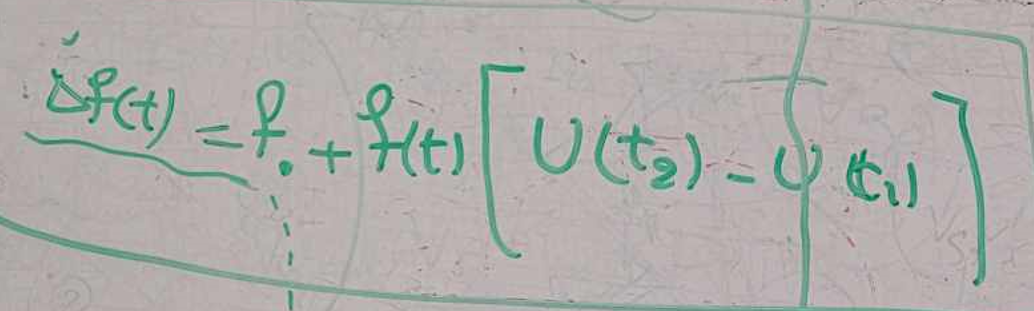

This is the equation, requested by Dr. Azizi during our meeting on the 15th of November, which I have been tasked to explore.

This will involve calculating GSFR, Frequency response, Delta Frequency and then Laplace transforming the result to achieve the Power required to compensate for the Frequency Response after a generator loss.

**Phase 1**: Computing GSFR

    Based on the paper by Jesus, where he mentions taking his values from the paper "a low order system frequency response", I need to calculate GSFR using the following values, where 𝑅 , 𝐷 , 𝐾𝑚 , 𝑇𝑅 , 𝜁 , and 𝜔𝑛 respectively represent the effects of the governor droop, frequency dependence of load, mechanical gain factor, reheat time constant, damping factor, and natural frequency of the system. This should result in identical values as Jesus uses in his paper.

    The paper "a low order system frequency response" has the following list of values, and they will be recalculated and confirmed before use.

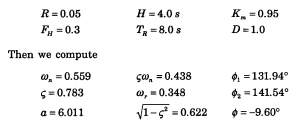

%Initializing the values for computation
R = 0.05;
H = 4.0;
K = 0.95;
Fh = 0.3;
Tr = 8.0;
D = 1.0;

    The values as computed in the paper could be used, as shown above, or they can be recalculated. This will be done for completeness, to ensure the accuracy of the values used. A P-step of 0.3 will be used for this example. (For Jesus' paper, all that matters is the magnitude, hence why it is not negative such as the original SFR paper)

Ps = 0.3; %Initializing the P-step value

    The first 2 values,  𝜔𝑛  and  𝜁 are calculated by Jesus using the following eqautions.

    These can be constructed as symbolic functions, by using a declared symbolic variable t

%Initializing t
syms t s

%Calculating  𝜔𝑛 
wn2 = (D*R+K)/(2*H*R*Tr)

wn2 = 0.3125

wn = sqrt(wn2)

wn = 0.5590


%Calculating  𝜁 
c = (((2*H*R)+(((D*R)+(K*Fh))*Tr))/(2*(D*R+K)))*wn 

c = 0.8609

    In the process of calculating  𝜁 , it was uncovered that the values were not aligning with the expected values from the paper "a low order system frequency response".  𝜁 is not 0.783, as indicated by the original paper. It seems to be 0.8609, as confirmed using a manual calculation.  𝜔𝑛  is the same, so I am unsure where the variation has been introduced.

    After a meeting with fellow student Emico, whom has also** created a LiveScript based solution** for this task, we compared our LiveScript Values, and found the same result. A difference in  𝜁 causing differences in our Phi values, from the one stated earlier. We however, had the same value between Emico and I.

    The decision was made to proceed.

    The next step, as described by Jesus, is to calculate:

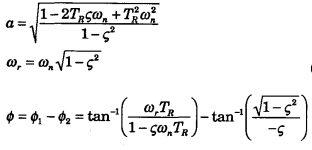

    Which can be done as follows, using the variables computed earlier. It is important to note that the calculation is done in Radians. This was **spotted during the meeting with Emico**, as Matlab's atan() function uses Radians, and using degrees, as the paper "a low order system frequency response" does, causes the response curve to **deviate** from expected results.

%Calculating alpha
a = sqrt((1-2*Tr*c*wn+(Tr^2)*(wn^2))/(1-(c^2)))

a = 7.1677


%Calculating 𝜔r
wr = wn*(sqrt(1-(c^2)))

wr = 0.2844


%Calculating the angle (In Radians)
phi = atan((wr*Tr)/(1-c*wn*Tr))-atan(sqrt(1-(c^2))/(-c))

phi = -0.1400

    Lastly, the frequency response can be computed, as the function f(t). This function, according to the graph Jesus published in his paper, is in per units, not a direct comparison to the powergrid. Hence, the original frequency is not 50, and should be set to 1. 

    Computing the function f(t), for the previously derived and stated variables, is done as follows:

ft = 1 - ((R*Ps)/(D*R+K))*(1+a*exp(-c*wn*t)*sin(wr*t+phi));

    which produces the following graph:

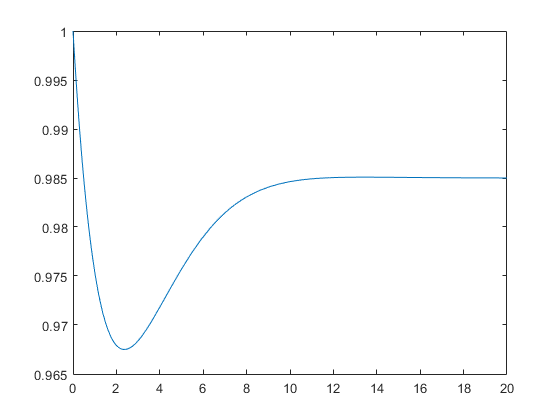

fplot(ft)
xlim([0 20])
ylim([0.965 1])

    Given the assumptions from the SFR paper, which states that the oscillations beyond the first dip should be suitably dampened, this curve looks appropriate. Comparing to a previously constructed **Simulink** model, Jesus' paper, and the older "a low order system frequency response", the results are as expected.

**Phase 2**: Creation of the GSFR function and the Delta Frequency **in the Laplace domain**

    This portion of the paper covers the rest of the components required in the ∆𝑃(𝑠) = ∆𝐹(𝑠)/𝐺𝑆𝐹𝑅(𝑠) equation. This is then used to find the  ∆𝑝(𝑡) for any P-step and correction factor, 𝛽, by finding the inverse Laplace of ∆𝑃(𝑠). 

    To begin, a transfer function can be constructed to convert the GSFR function to the Laplace domain, as shown in the below function from Jesus' paper:

    In LiveScript, this is done as fellows:

%Construct the transfer function
num = [Tr 1];
den = [1 2*c*wn wn^2];
transferFunc = tf(num,den);

%Define the symbolic function
GSFR = ((R*(wn^2))/(D*R+K))*transferFunc


GSFR =
 
     0.125 s + 0.01563
  -----------------------
  s^2 + 0.9625 s + 0.3125
 
Continuous-time transfer function.



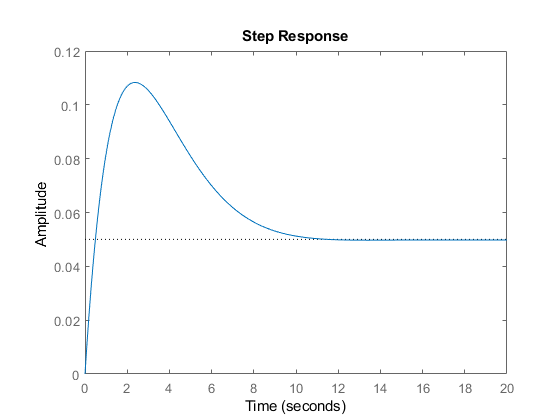


%Graphing the Output to compare
step(GSFR)
xlim([0 20])
ylim([0 0.12])

    The next stage, which is defining Delta Frequency, requires the following formula:

    To construct this function, a new Frequency nadir will need to be calculated. A unit step function at t1 and t2 (which, per Dr. Azizi's request in our meeting, will be modified to the singular 't - tau' step function) needs to becomputed as well. This will involve deciding on a Correction Factor, computing the value of tau, and the old frequency nadir.

%Defining the frequency Nadir
fs = 1 - ((R*Ps)/(D*R+K));
tn = (1/wr)*atan((wr*Tr)/(c*wn*Tr-1));
fn = 1 - ((R*Ps)/(D*R+K))*(1+a*exp(-c*wn*tn)*sin(wr*tn+phi));

%Declare the correction Factor
B = 0.8;
Dtr = fs - fn;
%The new frequency Nadir with the correction Factor
fnew = B*Dtr + fn;


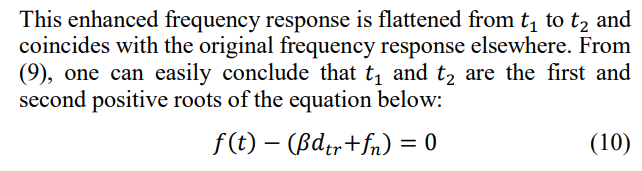

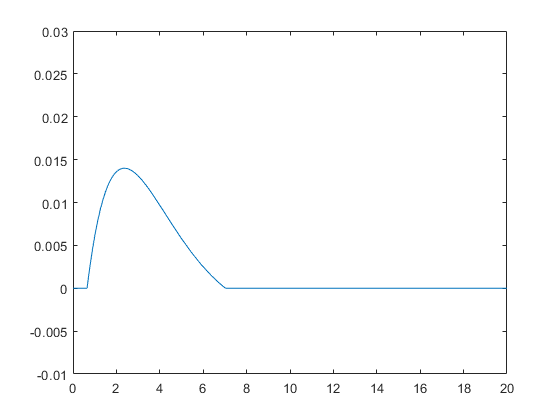

%Declare and compute Tau, based on Jesus' work
sympref('HeavisideAtOrigin',1);
tau = vpasolve(ft-(B*Dtr+fn)==0,t);
tau2 = vpasolve(ft-(B*Dtr+fn)==0,t,tau+tn);

%Define the function Delta Frequency, and plot in the time domain
dft = vpa((fnew - ft)*(heaviside(t-tau) - heaviside(t-tau2)));
fplot(dft)
xlim([0 20])
ylim([-0.01 0.03])

    Delta Frequency can now easily be derived for the Laplace domain, for use in the function ∆𝑃(𝑠) = ∆𝐹(𝑠)/𝐺𝑆𝐹𝑅(𝑠)

**Phase 3**: Find Delta p(s)

    Using a new symbolic variable s, Laplace domain functions can be made of the previously derived functions. These can then be symbolically solved, and an inverse Laplace function can be applied to acquire Delta p(s), the required extra injection to ensure 𝑓 𝑛𝑒𝑤(𝑡).

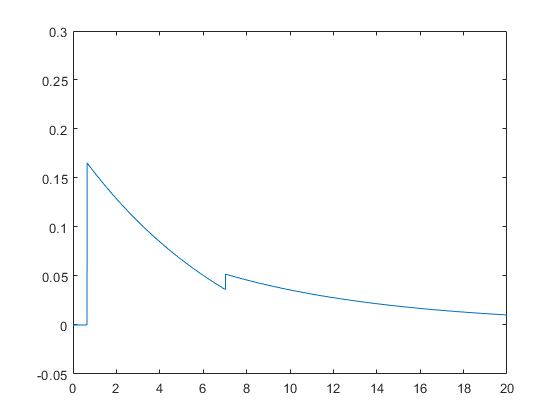


dFs = vpa(laplace(dft));

Gsfr = vpa(((R*(wn^2))/(D*R+K))*((1+Tr*s)/((s^2)+2*c*wn*s+(wn^2))));

dPs = vpa(dFs/Gsfr);
dpt = vpa(ilaplace(dPs));

fplot(dpt, [0 20])
%plot(datax,datay)
xlim([0 20])
ylim([-0.05 0.3])